## Motivation

The goal of this script is to first demonstrate reconstruction of a 2D sparse, latent image in the spatial domain using compressed sensing. The following linear equation governs the system:


$$y = Ax = \Phi \Psi x$$


where $y \in \mathbb{C}^{M \times M}$is the measurement in the spatial frequency domain (k-space), $x \in \mathbb{C}^{N\times N}$is the latent image in the spatial domain (r-space) and $A$is the sensing matrix comprised of a sampling matrix,$\Phi$ , and a sparsifying basis, $\Psi$.

## Introduction

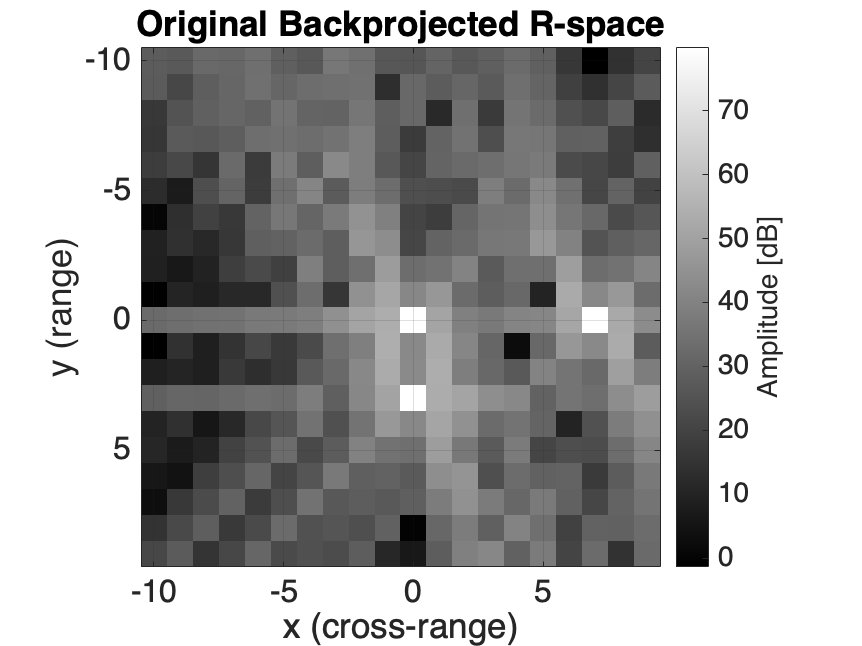

% load the sd backprojected image
output = load("data/truth_sd.mat");
output = output.output;

% extract the backprojection spatial domain image
x = output.rx_signal_bp;
x_array = output.x_array;
y_array = output.y_array;
N = size(x_array,2);

% plot the original backprojected image
f = figure;
imagesc(x_array, y_array, 20*log10(abs(x.') + eps));
colormap("gray")

xlabel('x (cross-range)', 'FontSize', 16)
ylabel('y (range)', 'FontSize', 16)
axis square
grid on
c1 = colorbar;
c1.Label.String = 'Amplitude [dB]';
set(gca,'FontSize',16)
title('Original Backprojected R-space')

Apply the sparsifying transformation: $\alpha \in \mathbb{C}^{N \times N} = \Psi x$, then vectorize such that $\alpha \in \mathbb{C}^{N^{2} \times 1}$

% define the forward and reverse operators A and AH
A = @(x, Phi) Phi * reshape(fft2(x),[],1);
AH = @(r, Phi, N) ifft2(reshape(Phi' * r, N, N));

Create a sampling matrix ($\Phi \in \{0,1\}^{M \times N^{2}}$) which samples 50% of the coefficients of $\alpha$

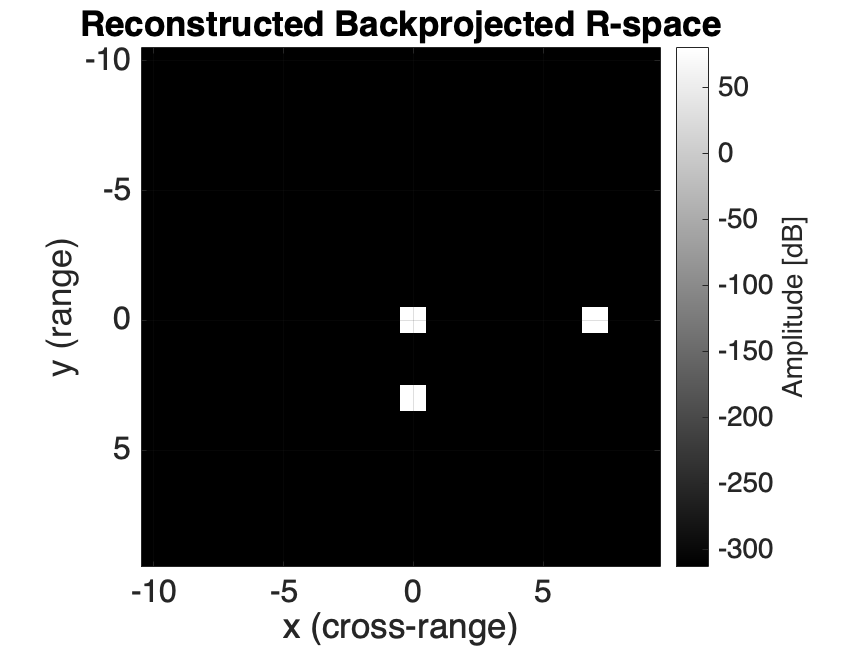

I = eye(N*N);
idx = rand(N*N,1) > 0.5;

% extract rows of the identity matrix corresponding to 50%
% sampling
Phi = I(idx,:);

% apply the forward operator to form the measurement
y = A(x, Phi);

% solve using OMP
x_hat = omp(y, A, AH, Phi, N, 3);

% plot the reconstructed backprojected image
f = figure;
imagesc(x_array, y_array, 20*log10(abs(x_hat.') + eps));
colormap("gray")

xlabel('x (cross-range)', 'FontSize', 16)
ylabel('y (range)', 'FontSize', 16)
axis square
grid on
c1 = colorbar;
c1.Label.String = 'Amplitude [dB]';
set(gca,'FontSize',16)
title('Reconstructed Backprojected R-space')